options = bodeoptions;
options.FreqUnits = 'Hz';
load("LAG_notch_elev_tacho.mat")

figure;
gain = 10;
elev_theco_gain = gain;
bode(gain*simulation_elev_techo_plant,options)
title('Gain added Bode')
hold on
bode(gain*sys_mes_elev_thaco,options)
grid on

## PRINT

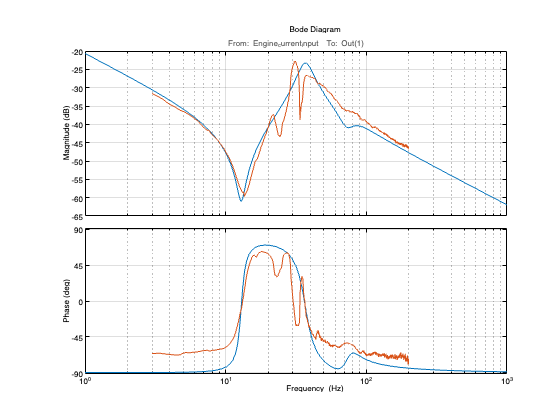

saveas(gcf,'/Users/ohadformanair/Documents/project_plots/elev_theco_plent_sim_mes.png')

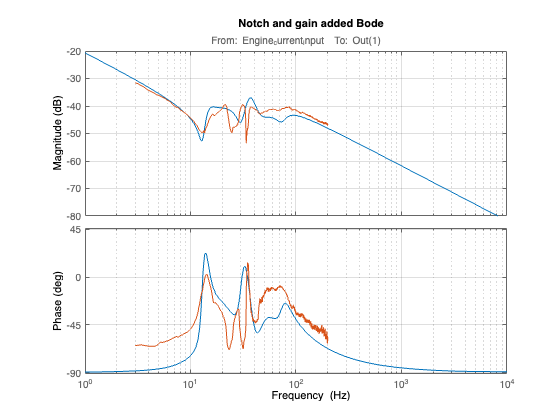

load('new_notch_elev_techo.mat')
figure;
elev_theco_notch =tf(new_notch_elev_techo);


bode(gain*elev_theco_notch*simulation_elev_techo_plant)
hold on
bode(gain*elev_theco_notch*sys_mes_elev_thaco)

title('Notch and gain added Bode')
hold off
grid on

sys_elev_theco = gain*elev_theco_notch*simulation_elev_techo_plant;
opts = pidtuneOptions('PhaseMargin',90);
[C_pi_elev_techo,info] = pidtune(sys_elev_theco,'PI',280,opts)

C_pi_elev_techo =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 104, Ki = 2.31e+04
 
Continuous-time PI controller in parallel form.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 280
           PhaseMargin: 53.4216




Kp_elev_techo =C_pi_elev_techo.Kp;
Ki_elev_techo =C_pi_elev_techo.Ki/60;

PI_elev_techo = tf(1/s*Ki_elev_techo+Kp_elev_techo);



sys_control = PI_elev_techo*sys_elev_theco;
grid on

figure;
margin(sys_control*LAG_notch_elev_tacho)
%sisotool(sys_control)
xlim([1,200])
grid on

## PRINT

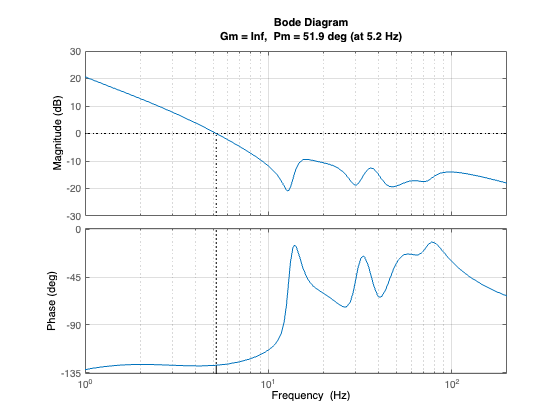

saveas(gcf,'/Users/ohadformanair/Documents/project_plots/elev_theco_sim_controlled.png')

figure;
elev_theco_PC_mes = PI_elev_techo*gain*new_notch_elev_techo*sys_mes_elev_thaco;
margin(elev_theco_PC_mes*LAG_notch_elev_tacho)
grid on
xlim([1,200])

## PRINT

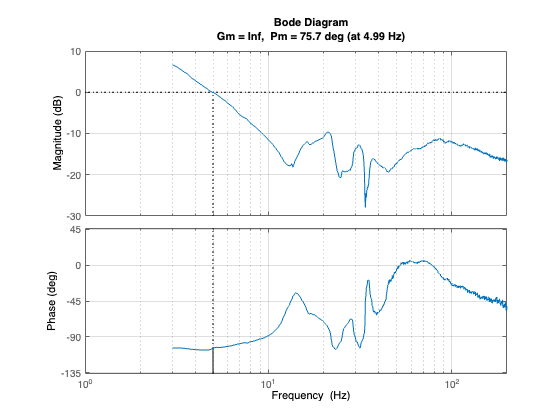

saveas(gcf,'/Users/ohadformanair/Documents/project_plots/elev_theco_mes_controlled.png')

elev_theco_notch =tf(elev_theco_notch*LAG_notch_elev_tacho);